# Parallel axis theorem

## What we're going to do:

In this FAQ, we're going to define the 3 dimensional version of the popular parallel axis theorem.  

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Starting the derivation:

Consider the following:

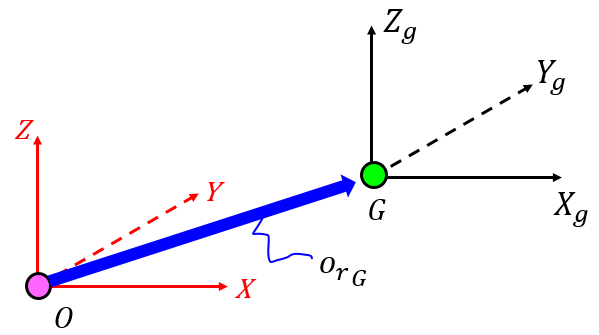

The *G-frame* represents a body fixed frame positioned at the Centre of mass(CM) of the body.  We know the Inertia matrix for this *G-frame* and write it as:

$I_G = 
\pmatrix{
^GI_{XX} & ^GI_{XY} & ^GI_{XZ} \cr
^GI_{XY} & ^GI_{YY} & ^GI_{YZ} \cr
^GI_{XZ} & ^GI_{YZ} & ^GI_{ZZ} \cr
} 
}$      where      $\matrix{ ^GI_{ZZ} = \int (x_g^2 + y_g^2) \thinspace dm \cr
^GI_{XY} = \int(-1*x_g *y_g) \thinspace dm \cr
}$       etc.  

And recall that because G is at the CM, we have:  $0 = \int x_g \enspace dm = \int y_g \enspace dm = \int z_g \enspace  dm$

The *0-frame* is parallel to the *G-frame*.  We wish to determine the inertia matrix of the body relative to the *0-frame*.  The position of the *G-frame* relative to the *0-frame* and expressed in components of the *0-frame*, is given by $\vec{ ^0r_G }$ where:


$$\vec{ ^0r_G } = \pmatrix{
a \cr
b \cr
c
}$$


So let's look at $^0I_{ZZ}$:

$^0I_{ZZ} = \int (x_0^2 + y_0^2) \thinspace dm$ = $ \int ( \quad (a+x_g)^2 + (b+y_g)^2 \quad) \thinspace dm$= $ \int ( a^2+2ax_g + x_g^2 +b^2 + 2by_g + y_g^2) \thinspace dm$


$$^0I_{ZZ} =$$
 
$$\int (a^2+b^2)dm + \int (x_g^2 + y_g^2) \thinspace dm + 2a\int x_gdm + 2b\int y_g dm$$


So finally:    $^0I_{ZZ} =$ $m.(a^2+b^2) \enspace + \enspace ^GI_{XX}$

Now let's look at $^0I_{XY}$ :


$$^0I_{XY} = \int(-1*x_0 *y_0) \thinspace dm =
\int (-1*(a+x_g) * (b+y_g) dm$$



$$^0I_{XY} = -1*\int ab + ay_g + bx_g + x_gy_g dm = \int (-1*a*b)dm \enspace + \enspace ^GI_{XY} \enspace + \enspace \int -ay_gdm + \int-bx_g dm$$


So finally:   $^0I_{XY} = m. (-1*a*b) \enspace + \enspace ^GI_{XY} \enspace $

And by applying the same process we can compute similar values for $^0I_{yy}$and $^0I_{XZ}$, etc.  So let's summarise what we've just derived:

## Concluding the derivation:

Recall the diagram presented in the previous section:

  where $\vec{ ^0r_G } = \pmatrix{
a \cr
b \cr
c
}$   and   $\matrix{ ^0I_{ZZ} = \int (x_0^2 + y_0^2) \thinspace dm \cr
^0I_{XY} = \int(-1*x_0 *y_0) \thinspace dm \cr
}$     etc. 

From the derivations in the previous section we can now write:

$^0I $ = $\pmatrix{
^0I_{XX} & ^0I_{XY} & ^0I_{XZ} \cr
^0I_{XY} & ^0I_{YY} & ^0I_{YZ} \cr
^0I_{XZ} & ^0I_{YZ} & ^0I_{ZZ} \cr
} 
}$  =   $^GI \quad + \quad
m\times\pmatrix{
(b^2+c^2) & (-ab) & (-ac) \cr
(-ab) & (a^2+c^2) & (-bc) \cr
(-ac) & (-bc) & (a^2+b^2)

}$ 

## The implementation:

I've implemented the above formula into a MATLAB class called **inertia_parallel_local_to_desired_CLS**. Here's the implementation

dbtype inertia_parallel_local_to_desired_CLS


1     classdef inertia_parallel_local_to_desired_CLS
2         
3         properties  (SetAccess = protected)
4             I_local          = [];
5             mass             = [];
6             pos_CM_in_desired = []; 
7         end
8         
9         methods
10            function  OBJ = inertia_parallel_local_to_desired_CLS( ...
11                                         pos_CM_rel_to_desired, I_LOC, mass)
12                OBJ.I_local           = I_LOC;
13                OBJ.mass              = mass;
14                OBJ.pos_CM_in_desired = pos_CM_rel_to_desired;
15            end
16            %------------------------------------------------------------------
17            function I_desired = calc_I_GLOB(OBJ)
18                x_c  =  OBJ.pos_CM_in_desired(1);
19                y_c  =  OBJ.pos_CM_in_desired(2);
20                z_c  =  OBJ.pos_CM_in_desired(3);
21                        
22               A     =  [ (y_c^2 + z_c^2),         -x_c*y_c,         -x_c*z_c;
23 

The above implementation will work for either NUMERIC or symbolic variables.  Let's look at an example:

**An example (SYMBOLIC):**

syms m I_xx I_xy I_xz I_yy I_yz I_zz a b c

% define the LOCAL G-frame inertias
gI = [ I_xx, I_xy, I_xz;
       I_xy, I_yy, I_yz;
       I_xz, I_yz, I_zz ];
   
% define the position of G relative to the 0-frame (and in units of the 0-frame)  
r = [a,b,c].';       

% create an instance of the inertia_local_to_desired_CLS class
OBJ = inertia_parallel_local_to_desired_CLS(r, gI, m);

% compute the INERTIA relative to the 0-frame
OBJ.calc_I_GLOB()

$$ans = \left(\begin{array}{ccc} I_{\mathrm{xx}}+m\,\left(b^{2}+c^{2}\right) & I_{\mathrm{xy}}-a\,b\,m & I_{\mathrm{xz}}-a\,c\,m\\ I_{\mathrm{xy}}-a\,b\,m & I_{\mathrm{yy}}+m\,\left(a^{2}+c^{2}\right) & I_{\mathrm{yz}}-b\,c\,m\\ I_{\mathrm{xz}}-a\,c\,m & I_{\mathrm{yz}}-b\,c\,m & I_{\mathrm{zz}}+m\,\left(a^{2}+b^{2}\right) \end{array}\right)$$